# 基于状态空间表示的线性滤波系统

## 步骤一：规定输入和输出

规定输入函数$u\left(t\right)$和输出函数$y\left(t\right)$，分别进行拉普拉斯变换

clear;clc;warning off
syms sigma t; assume(sigma, 'real')
u_t = dirac(t)

$$u\_t = \delta (t)$$

y_temp = (1/sqrt(2 .* pi .* sigma.^2)) .* exp(-t.^2./(2.*sigma.^2))

$$y\_temp = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{t^{2}}{2\,\sigma^{2}}}}{2\,\sqrt{\pi }\,\sqrt{\sigma^{2}}}$$

% ricker wavelet
% y_t = (2 / (pi^0.25 * sqrt(3 * sigma))) * (1 - (t/sigma)^2) * exp(-t^2/(2*sigma^2))
U_s = laplace(u_t);
Y_s = laplace(y_temp);

## 步骤二：求解传递函数

通过拉氏变换之比，可以得到传递函数$G\left(s\right)$，发现在传递函数中存在误差函数$\textrm{erf}\left(\cdot \right)$

G_s = simplify(U_s/Y_s)

$$G\_s = -\frac{2\,{\mathrm{e}}^{-\frac{s^{2}\,\sigma^{2}}{2}}}{\mathrm{erf}\left(\frac{\sqrt{2}\,s\,\left|\sigma \right|}{2}\right)-1}$$

同样，利用傅里叶变换之比，也可以得到传递函数的频率特征$G\left(\textrm{iw}\right)$

Y_iw = fourier(y_temp);
U_iw = fourier(u_t);
G_iw = simplify(Y_iw / U_iw)

$$G\_iw = {\mathrm{e}}^{-\frac{\sigma^{2}\,w^{2}}{2}}$$

若直接对误差函数进行积分，或利用傅里叶变换求解，需要**对参数进行规定后拟合**，此时进行实际的采样绘制频率特征，会发现频率特征表现为**无衰减**的周期性变换，难以拟合

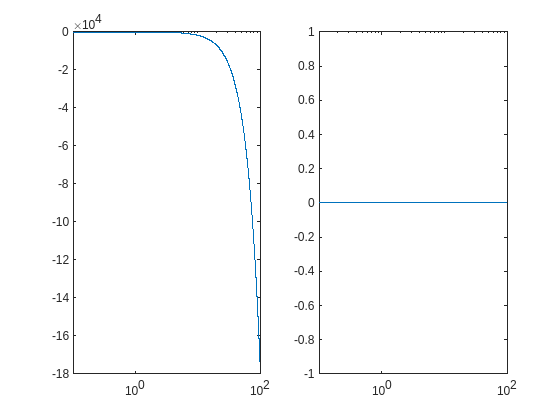

syms w; sigma_val = 2; % 方差（ms）
freq = 0:0.1:100;
resp = subs(subs(G_iw, sigma, sigma_val), w, freq);
phase = angle(resp);
mag = 20 .* log10(abs(resp));
figure();
subplot(1,2,1); semilogx(freq, mag)
subplot(1,2,2); semilogx(freq, phase*57.3)

最小二乘估计可以发现拟合完全失败

frdata = frd(eval(mag .* (cos(phase) + sin(phase) .* 1i)), freq);
sys = tfest(frdata, 2);
[mag, phase, wout] = bode(sys);
figure();
subplot(1,2,1); semilogx(wout, squeeze(mag))
subplot(1,2,2); semilogx(wout, squeeze(phase))

考虑到拟合失败的可能原因是由于高斯分布在$\left(-\infty ,+\infty \right)$均有值存在，因此参考信号处理中窗函数的概念，采用Hann窗对高斯分布的取值进行限制，并通过采样进行拟合。现假设单位时间$t_{unit}$上存在方差$\sigma$，为了尽可能高精度的估计，选取采样时间为$0.1t_{unit}$

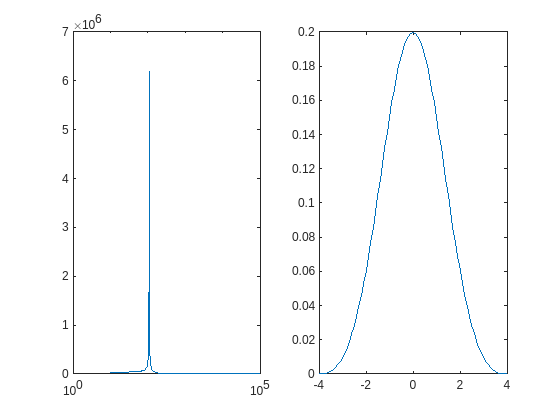

t_inter = 0.1; t_val = -2*sigma_val:t_inter:2*sigma_val; % 假设1ms采样一次（和目前程序所能处理的最大速度持平）
y_val = subs(subs(y_temp, sigma, sigma_val), t, t_val);
y_val = y_val .* hann(length(y_val))';
plot(t_val, y_val)

此时可以通过时域（time-domain）上的响应进行最小二乘拟合，获得传递函数

u_t = zeros(size(t_val)); u_t(1) = 1; Nx = length(t_val);
tfdata = iddata([zeros(1, Nx), eval(y_val), zeros(1, Nx)]', [zeros(1, Nx), u_t, zeros(1, Nx)]', 1); % Ts = 1
np = 4; % Number of poles
% nz = 2; % Number of zeros
sys = tfest(tfdata, np)

sys =
  From input "u1" to output "y1":
   -0.01705 s^3 + 0.008909 s^2 - 0.002075 s + 0.000319
  ------------------------------------------------------
  s^4 + 0.171 s^3 + 0.02488 s^2 + 0.001605 s + 5.055e-05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 3
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "tfdata".
Fit to estimation data: 95.07%                     
FPE: 8.343e-06, MSE: 7.558e-06                     
 
Model Properties


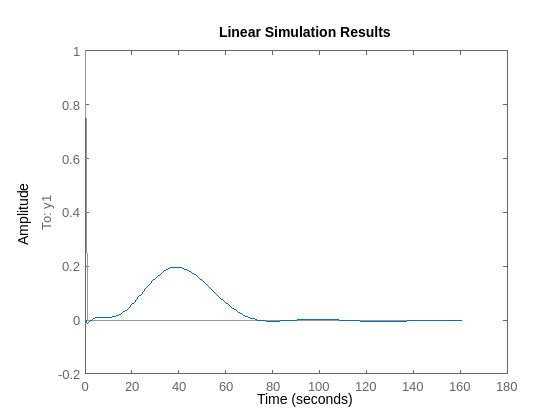

figure()
u_test = [u_t, zeros(1, Nx)]';
t_test = 0:1:length(u_test)-1;
lsim(sys, u_test, t_test)  % 验证拟合（注意要往后延伸），注意此时验证的是沿采样时间1ms进行更新时候的图像，横坐标是步长

## 步骤三：转移到状态空间

在上述步骤中，我们已经求得频率域的传递函数


$$G(s) = \frac{Y(s)}{U(s)} = \frac{b_{m} s^{m} + b_{m-1}s^{m-1}+\dots+b_{1}s+b_0}{s^{n}+a_{n-1}s^{n-1}+\dots+a_{1}s+a_0}$$


由于$m<n$，可以判断系统为严真情形，由此获得对应的状态空间（状态方程）描述为


$$\begin{array}{rcl}
\dot{{\bf x}} &=& \left[\matrix{
-a_0 & \dots   & a_{n-2} & -a_{n-1} \cr
1      &            &              & 0 \cr
        & \ddots &              & \vdots \cr
        &            & 1           & 0} \right]
{\bf x} + \left[ \matrix{1\cr 0 \cr \vdots\cr 0} \right]u \\
y &=& \left[ \matrix{0, \cdots, 0, b_m, \cdots, b_0} \right] {\bf x}
\end{array}
$$


[A, B, C, D] = tf2ss(sys.Numerator, sys.Denominator);

可以基于状态空间得到其状态运动规律关系式（即状态方程的解）为


$${\bf x}(t) = e^{A(t-t_0)} \cdot {\bf x}_0 + \int_{t_0}^t e^{A(t-\tau)} \cdot Bu(\tau) d\tau$$


因此可以通过离散时间采样，求解不同时刻$y\left(t\right)$的响应

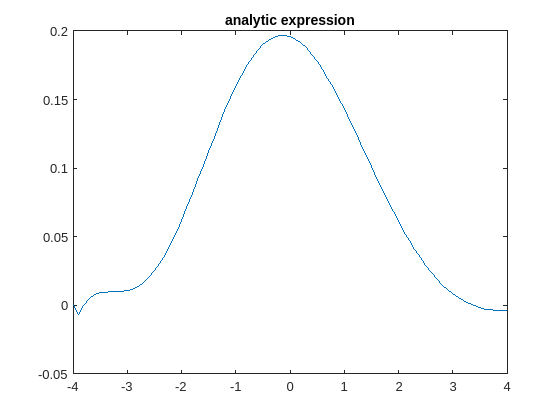

u_t = zeros(size(t_val)); u_t(1) = 1;
x_ss = zeros(np, 1); y_ss = zeros(size(t_val));
% 每采样一次(单位时间)进行一次更新
for idx = 1:length(t_val)
    y_ss(idx) = C * x_ss + D * u_t(idx);
    x_ss = expm(A) * x_ss + expm(A) * B * u_t(idx);
end
figure();
plot(t_val, y_ss); title('analytic expression');  % 通过状态方程得到的结果

## 步骤四：验证两者之间的误差

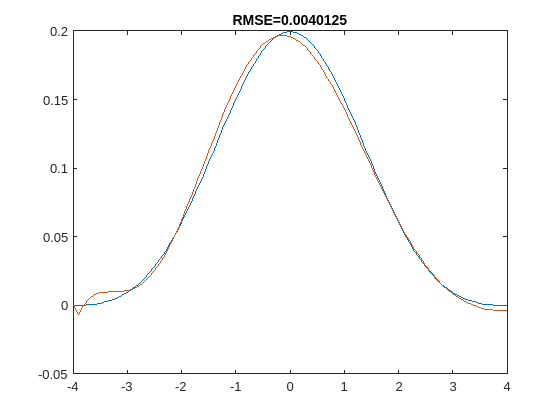

RMSE = sum(abs(eval(y_val) - y_ss)) / length(y_ss);
plot(t_val, y_val, t_val, y_ss)
title(['RMSE=', num2str(RMSE)])

## 附录

考虑更一般的情况，对于**零初态线性定常系统**，在接受单位脉冲响应$\delta \left(t\right)$作为输入的情况下，可以得到脉冲响应


$$H(t) = C e^{At} B + D \delta(t)$$


 那么可以得到任意时刻的输出$y\left(t\right)$，计算公式为


$$y(t) = \int_{t_0}^t H(t-\tau) u(\tau) d\tau$$


上式就是进行卷积，此时回归到了问题的原点，在已知输入$u\left(t\right)$的情况下，和高斯核$H\left(\cdot \right)$卷积得到信号